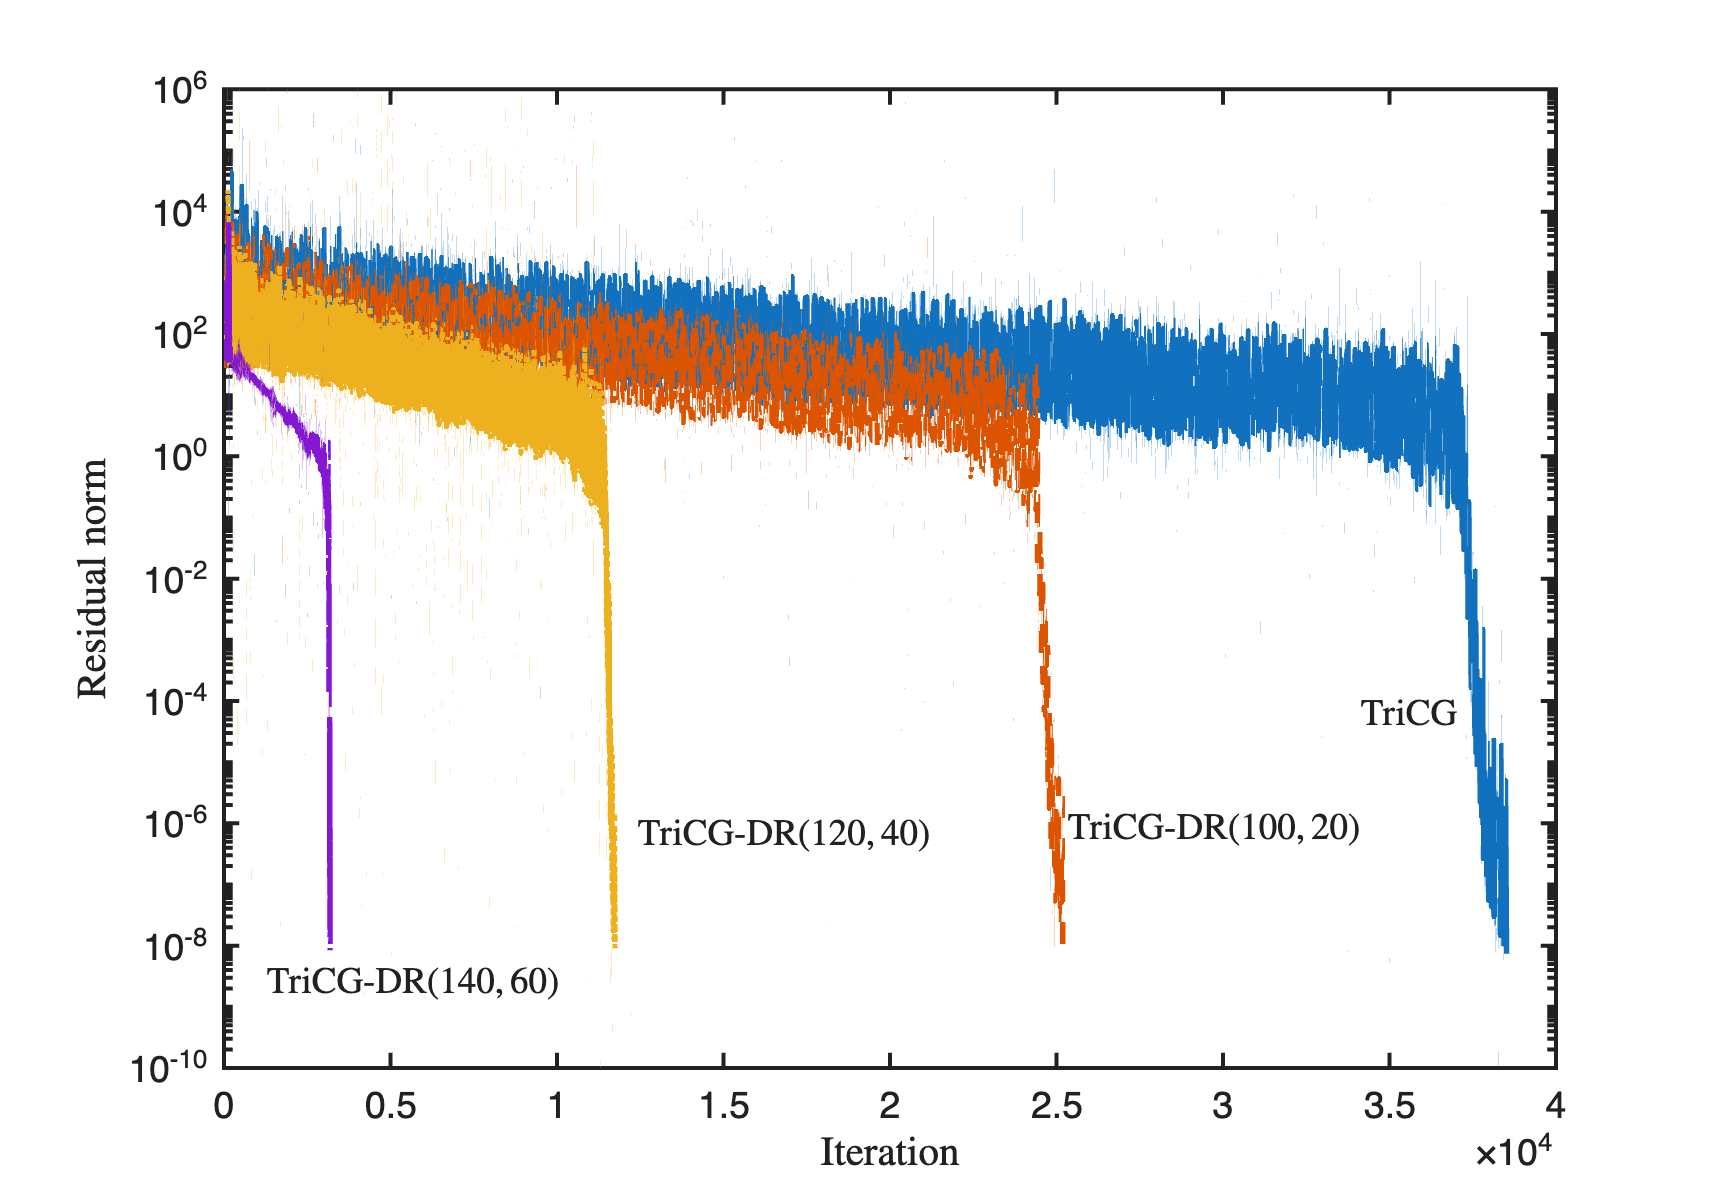

clc; close all; clearvars;

A = [linspace(0, 800, 2000), linspace(1e3, 1e5, 60)]';
m = length(A);
n = m;
A = spdiags(A, 0, m, n);

rng(100);
b = rand(m, 1);
c = rand(n, 1);

tol = 1e-8;
stol = 1e-10;  % \vareps_{svd}
exres = true;
maxit = 40000;
maxcycle = 80;
show_info = true;
ks = [20, 40, 60];

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres, show_info=show_info);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;

lgd_title = cell(1, 1+length(ks));
lgd_title{1} = "TriCG";

line_style = {'--', ':', '-.'};
for i = 1:length(ks)
    k = ks(i);
    p = k + 80;
    [~, ~, ~, resvec2] = tricgdr(A, b, c, [], [], k, p, tol, maxcycle, ...
                        maxit=maxit, stol=stol, exres=exres);

    lgd_title{i+1} = sprintf("TriCG-DR$(%d,%d)\\,$", p, k);
    semilogy(0:length(resvec2)-1, resvec2, LineStyle=line_style{i});
end
hold off;

ylim([1e-10, 1e6]);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend(lgd_title, Location='northeast', Interpreter='latex', FontSize=14);

annotation("textbox", [0.7811 0.383 0.0903 0.04866], "String", "TriCG", ...
    "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.6109 0.256 0.1676 0.08066], "String", "TriCG-DR$(100,20)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.3606 0.251 0.1676 0.08066], "String", "TriCG-DR$(120,40)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.1452 0.1277 0.1676 0.08066], "String", "TriCG-DR$(140,60)$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");


exportgraphics(gcf, 'figs/fig1.pdf', Resolution=600);